# Lectura y limpieza de datos Isla Arena

### Computación y análisis de datos geofísicos

### 2026-2 

### Profesor: Dr. Ismael Mariño Tapia

### Alumna: Tut Mengual Karla Nayeli 

## Introducción

El análisis de datos necesita la correcta lectura y limpieza de los registros obtenidos por los instrumentos, debido a que es común que los datos crudos contengan valores anómalos, ruido o periodos en los que el instrumento no se encontraba en condiciones adecuadas de medición, por ello antes de realizar una interpretación física de las variables registradas, es necesario revisar, organizar y depurar la información.

Se realizó la lectura y procesamiento de los datos obtenidos con un ADCP para identificar posibles errores, eliminar registros no confiables y preparar la información para su análisis y así asegurar que las variables analizadas como la temperatura, la presión y las velocidades, representen correctamente las condiciones reales del medio marino.

## **1. Inspección de datos **

Primero se importa al espacio de trabajo el archivo S100629A011_IslArena_1.mat el cual contiene las mediciones del ADCP

Luego se realiza una inspección la estructura del archivo para identificar los parámetros de configuración del instrumento, esto se visualiza en Config, que es donde se almacenan los parámetros de operación programados en el ADCP, de ahí podemos tener información de: número de celdas de medición, tamaño de celda, distancia de blanqueo y los parámetros asociados al modo de muestreo en ráfagas, incluyendo el número de muestras por ráfaga y la frecuencia de muestreo. 

A partir de la inspección de la estructura` Config` del archivo de datos del ADCP Signature fue posible identificar los parámetros de operación del instrumento y la forma en que se adquirieron las mediciones. 

El ADCP Signature fue configurado para medir en modo ráfagas` (Burst),` lo cual se identifica en los parámetros `Burst_NSample = 1200` y `Burst_SamplingRate = 2 `dentro de la configuración del instrumento. Esto indica que el equipo registró 1200 muestras a una frecuencia de muestreo de 2 Hz, dos mediciones por segundo, lo que corresponde a una duración aproximada de 600 s (10 minutos) por ráfaga. 

Durante estas ráfagas el instrumento realiza múltiples pings acústicos de manera continua, pero los datos almacenados corresponden a perfiles de velocidad promediados cada 120 s, de acuerdo con el parámetro `Average_AverageInterval = 120 s.` Cada perfil promedio se calcula a partir de 480 pings acústicos `(Average_NPings = 480)`, lo que permite reducir el ruido asociado a las mediciones individuales y obtener estimaciones más estables de la velocidad de la corriente.

## 2. Extracción de datos

Se extraen desde la estructura `Data `algunas variables registradas por el ADCP durante las mediciones en modo ráfagas. 

a) Vector de tiempo Burst_Time, el cual se transpone y posteriormente se convierte al formato de fecha y hora de MATLAB mediante la función datetime, utilizando la opción `ConvertFrom datenum.` 

b) Nivel de batería (`Average_Battery`)

c) Rumbo del instrumento (`Average_Heading`)

d) Inclinación longitudinal o cabeceo (`Average_Pitch`) 

c) Inclinación lateral o balanceo (`Average_Roll`). 

d) Temperatura

e) Presión 

Se por transponer los vectores desde la extracción, debido a que cuando se inicio el procesamiento de los datos y se intentó graficar no coincidian los arreglos, por ello para facilitar el porceso, se realiza las transposición desde el inicio.

clear all,clc
load("S100629A011_IslArena_1.mat")
t1 = Data.Average_Time';
t = datetime(t1,'ConvertFrom','datenum');
Bat  = Data.Average_Battery';
Head = Data.Average_Heading';
Pitch = Data.Average_Pitch';
Roll  = Data.Average_Roll';

Se extraen la temperatura `(Average_Temperature)` y la presión `(Average_Pressure)`, las cuales permiten obtener información sobre las condiciones físicas del ambiente y estimar variaciones en el nivel del mar o en la profundidad

También las componentes de velocidad de la corriente: `VelEast(U) `correspondiente a la componente este–oeste, `VelNorth(V) `correspondiente a la componente norte–sur y `VelUp(W) `que representa la componente vertical del flujo. Las velocidades medidas por el ADCP se expresan en un sistema de coordenadas *ENU (East–North–Up),* el cual es un sistema de referencia local utilizado comúnmente en oceanografía.

Temp = Data.Average_Temperature';
Press = Data.Average_Pressure';

%Velocidades
U=Data.Average_VelEast;
V=Data.Average_VelNorth;
W=Data.Average_VelUp1;

Se extraen los valores de correlación acústica registrados por cada uno de los haces del ADCP. Indican la calidad de la señal acústica utilizada por el instrumento para calcular las velocidades del agua. 

La correlación mide qué tan consistente es el eco acústico recibido entre pulsos sucesivos, valores altos indican que la señal es confiable y que las mediciones de velocidad son más precisas, mientras que valores bajos pueden indicar ruido, baja concentración de partículas en el agua o pérdida de señal.

Estos parámetros son importantes para evaluar la calidad de los datos obtenidos por el instrumento antes de realizar el análisis de corrientes.

Cor1 = Data.Average_CorBeam1';
Cor2 = Data.Average_CorBeam2';
Cor3 = Data.Average_CorBeam3';
Cor4 = Data.Average_CorBeam4';

El rango de profundidades se define como `0.3:0.2:5.3`, donde el valor inicial corresponde a la primera distancia efectiva de medición desde el transductor, determinada por la distancia de blanking y la primera celda. 

El incremento de 0.2 m corresponde al tamaño de cada celda vertical del ADCP. El valor final de 5.3 se obtiene a partir de la configuración del instrumento, en número de celdas de medición` (Average_NCells = 26)` y del tamaño de cada celda `(Average_CellSize = 0.2 m)`, lo que define la profundidad total cubierta por el perfil de medición.

depth = 0.3:0.2:5.3

depth =     0.3000    0.5000    0.7000    0.9000    1.1000    1.3000    1.5000    1.7000    1.9000    2.1000    2.3000    2.5000    2.7000    2.9000    3.1000    3.3000    3.5000    3.7000    3.9000    4.1000    4.3000    4.5000    4.7000    4.9000    5.1000    5.3000


## 3. Visualización de datos

### a) Compás: Orientación e inclinación del aparato

En el primer panel se grafica la batería del equipo, paraverificar que el instrumento mantuvo un nivel de energía adecuado durante todo el periodo de medición. Si la batería presentara caídas importantes, podría afectar el funcionamiento del ADCP y comprometer la continuidad o confiabilidad de los datos.

En el segundo panel se muestra el heading, que corresponde a la orientación horizontal del instrumento. Graficarlo permite identificar si el ADCP mantuvo una dirección relativamente constante o si sufrió rotaciones durante la medición, lo cual podría influir en la interpretación de las componentes de velocidad.

En el tercer panel se representan pitch y roll, que describen la inclinación del instrumento. Estos parámetros son importantes para el control de calidad, ya que el ADCP debe mantenerse lo más vertical posible para medir correctamente las velocidades del flujo. Analizar su variación en el tiempo permite detectar periodos en los que el instrumento pudo haber estado inclinado o inestable, lo que podría afectar la representatividad de los datos de corriente.

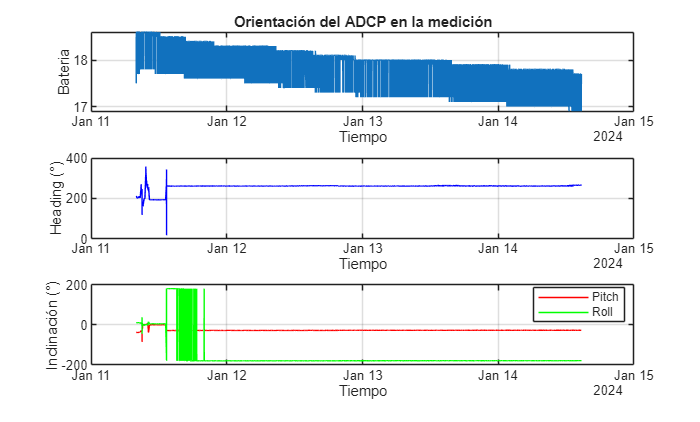

figure (1)
%Batería
subplot(3,1,1)
plot(t,Bat)
ylabel('Bateria')
xlabel('Tiempo')
title('Orientación del ADCP en la medición')
grid on

%Heading
subplot(3,1,2)
plot(t,Head,'b')
ylabel('Heading (°)')
xlabel('Tiempo')
grid on

%Pitch & Roll
subplot(3,1,3)
plot(t,Pitch,'r')
hold on
plot(t,Roll,'g')
ylabel('Inclinación (°)')
xlabel('Tiempo')
legend('Pitch','Roll','Location','best')
grid on

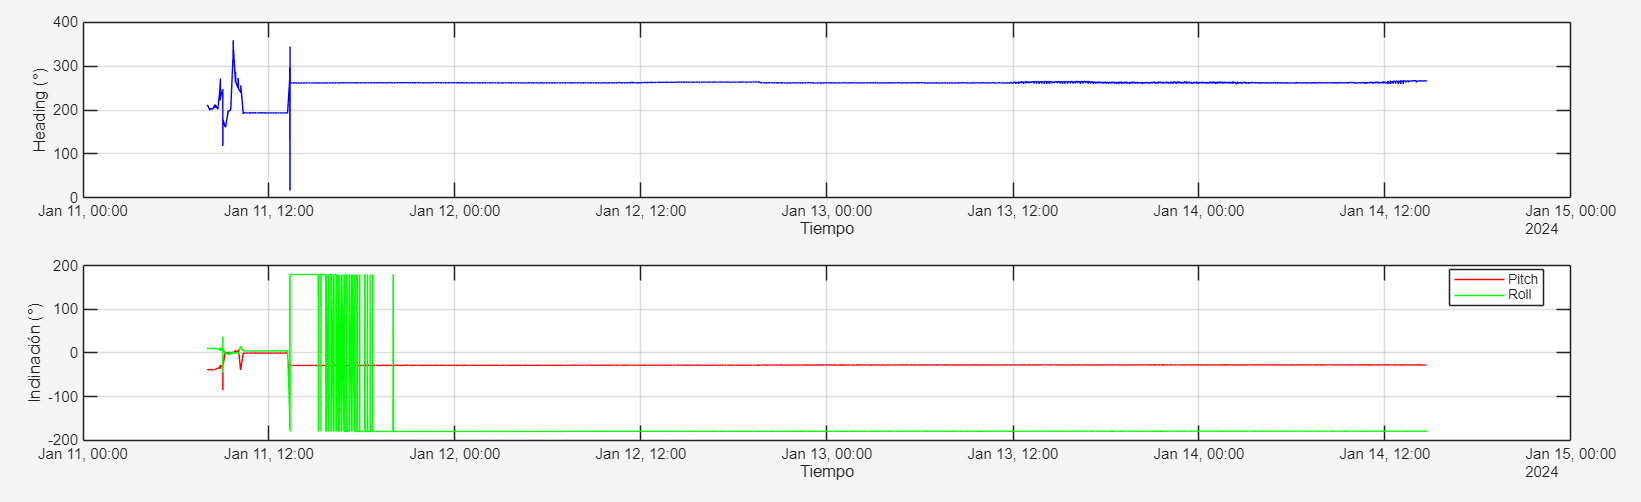

El segundo gráfico muestra la orientación del ADCP a través de los ángulos de pitch (rojo) y roll (verde) y de acuerdo con el criterio de calidad, los datos son confiables cuando la inclinación se mantiene dentro de un rango de 0 a 10°, mientras que valores mayores a ±30° se consideran no útiles, ya que pueden afectar las mediciones. Se observa que al inicio del registro existen variaciones en la orientación, especialmente en el roll, el instrumento no estaba estable, probablemente durante su instalación o manipulación, posteriormente los valores se vuelven más constantes, lo que sugiere que el ADCP permaneció en una posición fija en 0°, luego se observa un cambio en la inclinación, superando los 10°, por lo que las mediciones realizadas en ese periodo no son representativas de las velocidades.

### b) Presión y temperatura 

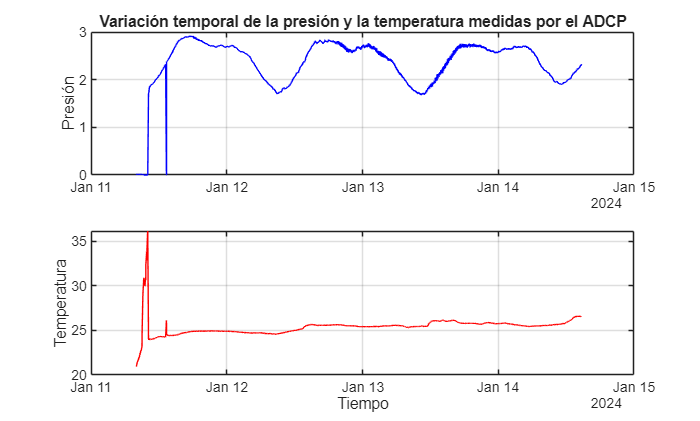

figure (2)
subplot(2,1,1)
plot(t,Press,'b')
grid on
ylabel('Presión')
title('Variación temporal de la presión y la temperatura medidas por el ADCP')

subplot(2,1,2)
plot(t,Temp,'r')
grid on
ylabel('Temperatura')
xlabel('Tiempo')

Se observa que en el inicio del registro hay cambios bruscos tanto en presión como en temperatura, lo que tal vez corresponde al momento en que el instrumento estaba siendo instalado o manipulado, por lo que esos datos iniciales no representan condiciones estables.

Posteriormente se estabilizan, la presión presenta una variación periódica entre aproximadamente, lo cual se puede interpretar como cambios en el nivel del agua asociados al ciclo de marea. La temperatura se mantiene alrededor de 24–26 °C, solo pequeñas fluctuaciones a lo largo del tiempo.

Una vez que el instrumento se estabiliza, los registros muestran comportamientos coherentes y continuos, con esto se considera que los datos son adecuados para el análisis de las condiciones hidrodinámicas del sitio.

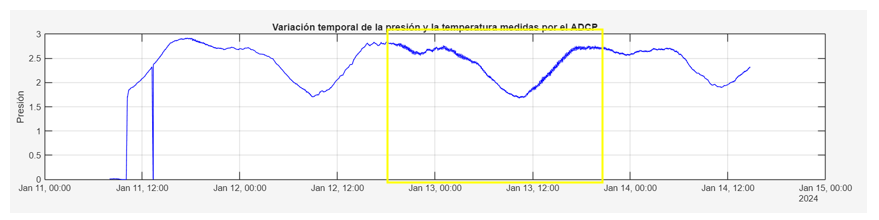

La presión registrada por el ADCP refleja las variaciones en la altura de la columna de agua sobre el instrumento, los cambios observados en la presión están asociados principalmente a las variaciones del nivel del mar producidas por el ciclo de mareas. Cuando el nivel del mar aumenta, la columna de agua sobre el instrumento es mayor y la presión registrada también aumenta y viceversa. En la serie temporal se observa una oscilación con un ciclo aproximadamente de 12 horas, que podría representar mareas semidiurnas.

### c) Velocidad 

La gráfica generada muestra la evolución temporal y vertical de la componente norte-sur de la corriente (V) medida por el ADCP. Esta visualización permite identificar patrones como la estratificación de la corriente, eventos de flujo intenso, posibles influencias mareales, y también detectar anomalías o vacíos en los datos.

Se transpone la matriz `V, `que originalmente tiene 56760 filas (tiempo) y 26 columnas (profundidad), por lo que al transponerla se obtiene una matriz de 26 filas (profundidad) y 56760 columnas (tiempo), para que coincida con las dimensiones de los vectores `depth` (1×26) y `t` (1×56760). 

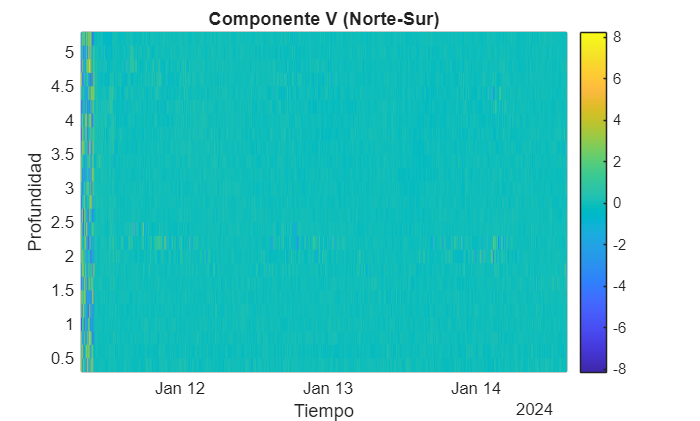

figure(3)
pcolor(t,depth,V')
shading flat
colorbar
xlabel('Tiempo')
ylabel('Profundidad')
title('Componente V (Norte-Sur)')

Los datos presentados muestran un patrón que sugiere baja fiabilidad. En la mayoría de los tiempos, los valores son constantes (0.5 y luego 0.2) en todas las profundidades, lo que indica posible ruido de fondo, valores por defecto o falta de medición real. Es probable que el instrumento haya presentado un fallo operativo, mala configuración o pérdida de señal. Por lo tanto, estos datos no son fiables para un análisis oceanográfico 

### d) Correlación

Se visualiza la correlación acústica registrada por el ADCP en función del tiempo y la profundidad, para observar cómo varía la calidad de la señal acústica a lo largo de toda la columna de agua durante el periodo de medición.

Graficar esta variable es importante porque la correlación es un indicador de la calidad de los datos de velocidad: valores altos significan que la señal acústica fue fuerte y coherente, mientras que valores bajos pueden indicar ruido o mediciones menos confiables. 

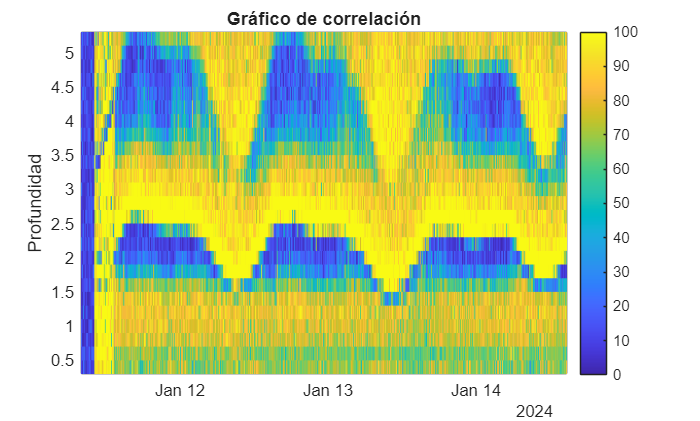

figure(4)
pcolor(t,depth,Cor1)
shading flat
colorbar
title('Gráfico de correlación')
ylabel('Profundidad')

El gráfico de correlación permite evaluar la calidad de la señal acústica registrada por el ADCP a lo largo del tiempo y la profundidad. Se observan valores de correlación altos en ciertas zonas, lo que indica que el instrumento recibió una señal adecuada para calcular las velocidades y que los datos pueden considerarse confiables.

Pero también aparecen zonas con correlación más baja en algunos momentos y profundidades, lo cual puede deberse a concentración de partículas en suspensión, turbulencia o a condiciones que debilitan la señal acústica o fallos del equipo. Estas áreas representan datos de menor calidad, por lo que durante el procesamiento es recomendable revisarlos o aplicar criterios de filtrado.

Aunque en el gráfico de correlación se observan valores altos en zonas de la columna de agua, lo que normalmente indicaría una buena calidad de la señal acústica, la información de pitch y roll muestra que el instrumento presentó inclinaciones mayores a 10° durante buena parte del registro.

Esta inclinación está fuera del rango óptimo de operación del ADCP (0–10°), por lo que, aun cuando la señal acústica tenga buena correlación, la geometría de los haces puede verse afectada, entonces la correlación puede indicar que la señal fue recibida correctamente, pero las velocidades calculadas podrían no representar con precisión el flujo real.

Al analizar la correlación es importante considerar también la orientación del instrumento, ya que una buena correlación no garantiza por sí sola que los datos de velocidad sean completamente confiables si el ADCP se encontraba inclinado.

## 4. Acotar en tiempo 

Se selecciona `a = 1201` porque cada burst contiene 1200 muestras (desde el índice 1 hasta 1200). El índice 1201 corresponde a la primera muestra del segundo burst, se elimina el primer rango de mediciones, para descartar el período inicial en el que el instrumento puede estar estabilizándose después del anclaje o presentar datos de mala calidad. El valor `b = 56760` se toma como el último índice disponible, abarcando el resto del registro hasta el final. 

a = 1201;
b = 56760;

Se realiza un recorte temporal a todas las variables que contienen datos medidos por el ADCP, utilizando los índices `a` y `b` para seleccionar únicamente el rango de interés, esto se hace para eliminar las mediciones iniciales (primer burst) y trabajar  solo con los datos a partir del segundo burst hasta el final del registro.

% Recorte temporal
t = t(a:b);
Press = Press(a:b);
Temp = Temp(a:b);
U = U(a:b, :);
V = V(a:b, :);
W = W(a:b, :);
Cor1 = Cor1(a:b);
Cor2 = Cor2(a:b);
Cor3 = Cor3(a:b);
Cor4 = Cor4(a:b);

Se selecciona un rango de celdas de profundidad de las mediciones, se toman todas las celdas desde la superior (c=1) hasta la inferior (d=26) y actualiza las matrices de velocidad (U, V, W). Igual se ajusta el vector de profundidad para que coincida con las celdas seleccionadas. 

% Rango de celdas
c = 1;      
d = 26;    
U = U(:, c:d);
V = V(:, c:d);
W = W(:, c:d);
depth = depth(c:d);

Se define que cada ráfaga contendrá 4, se obtiene dividiendo la duración total de una ráfaga (600 segundos) entre el intervalo de muestreo de cada perfil (120 segundos) y se considera que hay traslape entre ellos. 

Se calcula el número total de ráfagas dividiendo la cantidad de perfiles disponibles entre los 4 perfiles por ráfaga y se determina cómo se van a agrupar secuencialmente los datos.

rows = 4; %(600s/120s)
cols = length(t)/rows; % número de ráfagas

Se reorganizan las variables que antes eran series continuas en una estructura de ráfagas. Toma los datos y los agrupa en bloques, donde cada fila de las nuevas matrices representa una ráfaga completa y cada columna corresponde a un perfil individual dentro de esa ráfaga.

Los datos de correlación (`Cor1–Cor4`) solo se reorganizan en una matriz bidimensional usando `reshape`, y luego se aplica la transpuesta (`'`) para ajustar la orientación de filas y columnas. 

t_Bu = reshape(t, [rows, cols])'; % (cols×rows)
Temp_Bu = reshape(Temp, [rows, cols])';
Press_Bu = reshape(Press, [rows, cols])';
Cor1_Bu = reshape(Cor1, [rows, cols])';
Cor2_Bu = reshape(Cor2, [rows, cols])';
Cor3_Bu = reshape(Cor3, [rows, cols])';
Cor4_Bu = reshape(Cor4, [rows, cols])';

En las velocidades (`U`, `V`, `W`) se usa `reshape` para reorganizar los datos en una matriz tridimensional (celda, ráfaga y muestras). Como después de `reshape` las dimensiones no quedan en el orden deseado, se aplica `permute` para intercambiar las dimensiones y ordenar correctamente la información para el análisis.


U_Bu = permute(reshape(U', [size(U,2), rows, cols]), [2, 1, 3]);
V_Bu = permute(reshape(V', [size(V,2), rows, cols]), [2, 1, 3]);
W_Bu = permute(reshape(W', [size(W,2), rows, cols]), [2, 1, 3]);


Se extrae la primera columna de la matriz `t_Bu`, que contiene los tiempos de cada ráfaga. Como `t_Bu` está organizada con una fila por ráfaga y una columna por perfil dentro de la ráfaga, la primera columna corresponde al primer perfil de cada ráfaga, es decir, al instante en que comienza cada ráfaga. Es un vector columna (de tamaño `cols×1`)  y se utiliza como referencia temporal para representar variables promedio por ráfaga 

t_Ag1 = t_Bu(:, 1);

Dimensiones. Se generan estructuras de datos del tamaño adecuado (`n_celdas×n_rafagas`) 

n_celdas = length(depth);
n_rafagas = size(t_Bu, 1);

Se procesan los datos organizados en ráfagas. Con `squeeze `se eliminan las dimensiones sobrantes de tamaño 1 que se generan al seleccionar una única celda, dejando los datos en una matriz 2D (tiempo x ráfaga).

El ciclo calcula, para cada celda, el promedio temporal de las variables, dando como resultado una matriz donde cada fila es una celda y cada columna es de la ráfaga.

Así se reducen las dimensiones para obtener un valor medio por celda y ráfaga. Se obtienen matrices bidimensionales donde las filas representan las celdas de profundidad y las columnas las ráfagas.

for i = 1:n_celdas
    VmE(i, :) = mean(squeeze(U_Bu(:, i, :)));
    VmN(i, :) = mean(squeeze(V_Bu(:, i, :)));
    VmUp(i, :) = mean(squeeze(W_Bu(:, i, :)));
end

for i = 1:n_celdas
    Co1_mean(i, :) = mean(squeeze(Cor1_Bu(i, :, :)));
    Co2_mean(i, :) = mean(squeeze(Cor2_Bu(i, :, :)));
    Co3_mean(i, :) = mean(squeeze(Cor3_Bu(i, :, :)));
end

Se calculan los estadísticos para la temperatura y la presión registradas en ráfagas. Temp_Bu y Press_Bu son matrices donde cada fila representa una ráfaga y cada columna una medición dentro de ella. 

Con `mean(...,2)` se obtiene la temperatura media (Tmean) y la presión media (Pmean) de cada ráfaga.

Con `std(Temp_Bu,0,2)` la desviación estándar de la temperatura (Tstd)  para obtener cuánta variación hay dentro de cada ráfaga, 0 indica la desviación estándar muestral.

Nota: `2` se usa para resumir los datos a lo largo de la segunda dimensión (columnas) por que realice el cálculo de los estadísticos en cada elemento de la primera dimensión (las ráfagas). Se define porque  `mean` por defecto sólo lo realiza en la primera dimensión (filas).

Tmean = mean(Temp_Bu, 2); % temperatura media en cada ráfaga 
Pmean = mean(Press_Bu, 2); % presión media en cada ráfaga 
Tstd = std(Temp_Bu, 0, 2); %Desviación estándar (temperatura)

Se calcula la señal de marea eliminando el valor medio de la presión (`Pmean`), para poder obtener las variaciones del nivel del mar (`Tide`). Luego se define la altura del instrumento sobre el fondo (`ih = 1`) y se calcula la profundidad media del instrumento (`zmean`). 

Luego se cálcula la profundidad absoluta de cada celda (`prof_abs`) sumando la media a la distancia de cada celda respecto al sensor (`depth`)

Tide = detrend(Pmean, 0);    
ih = 1; % Altura del instrumento sobre el fondo
zmean = mean(Press); % Profundidad media del instrumento (usando la presión media de todo el registro)
prof_abs = -((zmean+ih)-depth) % profundidad positiva hacia abajo 

prof_abs = 1×26 single row vector
   -3.0978   -2.8978   -2.6978   -2.4978   -2.2978   -2.0978   -1.8978   -1.6978   -1.4978   -1.2978   -1.0978   -0.8978   -0.6978   -0.4978   -0.2978   -0.0978    0.1022    0.3022    0.5022    0.7022    0.9022    1.1022    1.3022    1.5022    1.7022    1.9022


## **e) Nivel del mar**

Se realiza un gráfico para visualizar la señal de marea y su relación con la corriente vertical. Se representa la velocidad en función del tiempo y la profundidad para analizar cómo cambian las corrientes en la columna de agua durante el ciclo de marea.

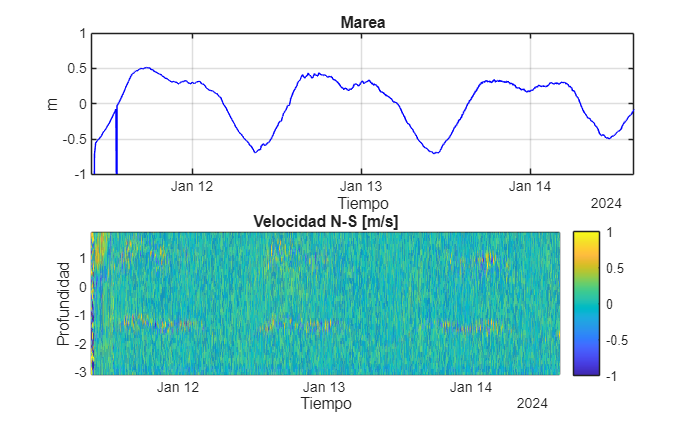

figure (5)
subplot(2,1,1)
%Marea
plot(t_Ag1, Tide, 'b-')
title('Marea')
ylabel('m')
xlabel('Tiempo')
xlim([t_Ag1(1) t_Ag1(end)]);
ylim([-1 1]);
grid on
%Velocidad
subplot(2,1,2)
pcolor(t_Ag1, prof_abs, VmE)
shading interp
colorbar
caxis([-1 1])
title('Velocidad N-S [m/s]')
ylabel('Profundidad')
xlabel('Tiempo')

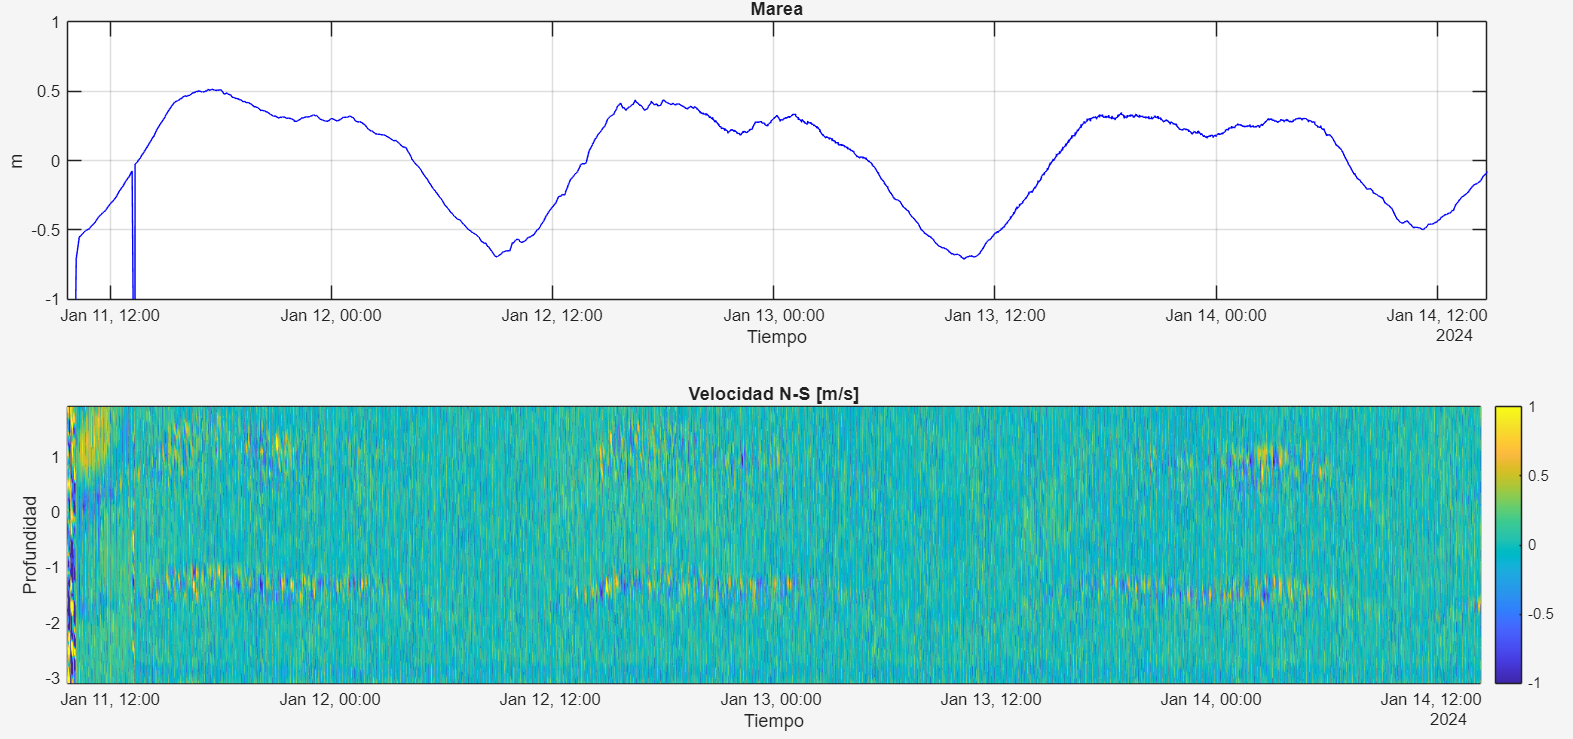

En el nivel del mar se observa una oscilación periódica de casi 12 horas y puede indicar un marea semidiurna (ciclo diario: dos ciclos completos de ascenso y descenso).

Se observa en las variaciones de velocidad durante el tiempo y la profundidad que en algunos momentos coinciden con las fases de la marea. Cuando el nivel del mar comienza a subir o bajar las corrientes se intensifican debido al movimiento del flujo de agua, la variación de las velocidades está relacionada con las oscilaciones del nivel del mar.

Pero debido a que el ADCP tuvo una inclinación cercana a 30°, las mannitudes velocidades pueden no ser representativas, ya que la inclinación puede introducir errores.

## F) Temperatura

Se realiza un gráfico de la tempertura para visualizar la evolución temporal de la temperatura y detectar valores anómalos en el registro, para identificar periodos donde las mediciones no son confiables, como los picos iniciales de temperatura, y distinguir cuándo los datos comienzan a estabilizarse y representan condiciones reales del agua.

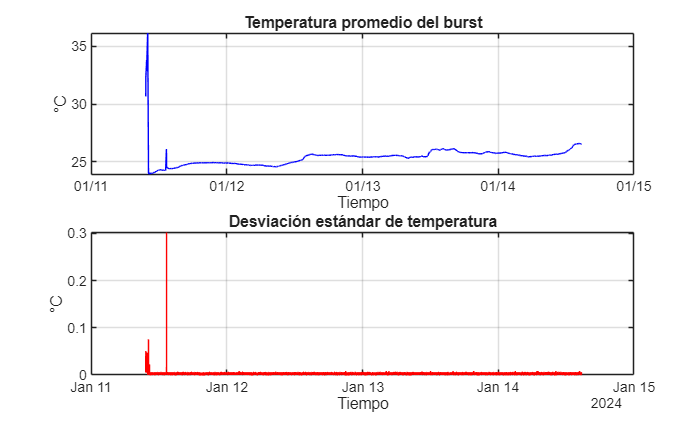

figure (6)
%Temperatura promedio
subplot(2,1,1)
plot(t_Ag1, Tmean, 'b-')
title('Temperatura promedio del burst')
xlabel('Tiempo')
ylabel('°C')
grid on
datetick
%Desviacion de la temperatura
subplot(2,1,2)
plot(t_Ag1, Tstd, 'r-')
title('Desviación estándar de temperatura')
xlabel('Tiempo')
ylabel('°C')
grid on

Al inicio del registro hay valores altos de temperatura comporados por los valores siguientes. Esto se puede deber a que  durante los primeros bursts, el ADCP aún no estaba estabilizado en el agua o estaba fuera, registrando la temperatura del ambiente o el equipo pudo calentado por la radiación solar. Luego la temperatura desciende y se estabiliza entre 25 y 26 °C, con una desviación estándar muy baja, lo que indica mediciones más representativas de la temperatura del agua.

## ***Análisis y justificación***

A partir de las gráficas generadas se observa que aunque el ADCP registró señales acústicas con valores de correlación altos en varias celdas, las velocidades calculadas no muestran un comportamiento coherente.

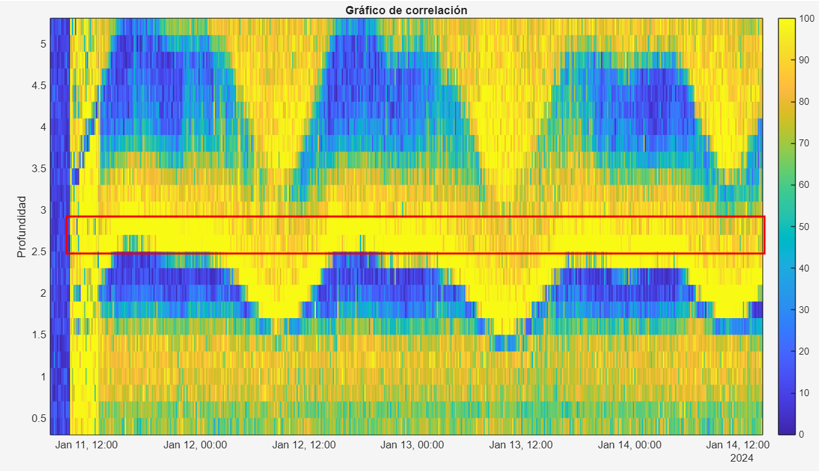

Al comparar con la gráfica de la componente de velocidad V, se observa que en muchos de los periodos donde la correlación es mayor las velocidades registradas son cercanas a cero. Esto indica que aunque el instrumento detecta una señal acústica congruente, el cálculo de las velocidades no muestras las variaciones reales del flujo.

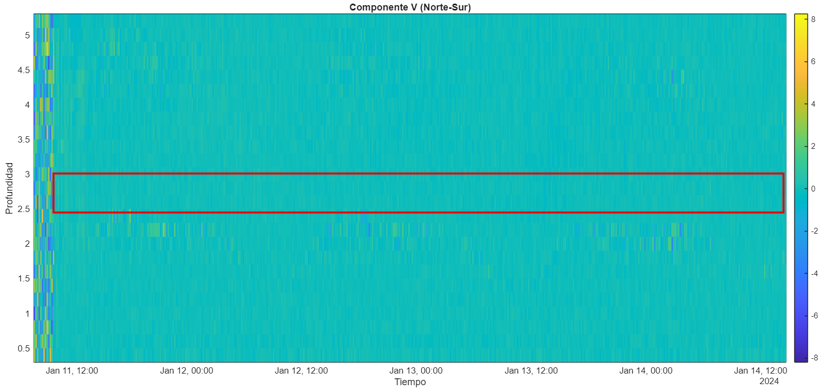

Esto puede ser ocasionado a errores debido de la inclinación del ADCP que se observó en el gráfico del pitch y roll que es mayor a 10°, esto  afecta la reconstrucción de las componentes de velocidad a partir de los haces acústicos. 

Entonces aunque la correlación indica una buena señal, las velocidades obtenidas no pueden interpretarse corrrectamente ya que no no son completamente confiables para un análisis de la dinámica de corrientes.

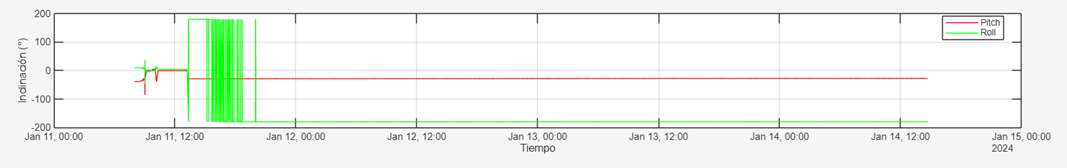

## **Conclusiones **

A partir del procesamiento y análisis de los datos obtenidos con el ADCP se observó el comportamiento temporal de algunas variables como la temperatura, la presión y el nivel del mar. La señal de marea muestra un patrón semidiurno definido, lo cual indica que el registro de presión captó adecuadamente las variaciones del nivel del mar durante el periodo de medición.

La temperatura promedio de las ráfagas presenta valores estables a lo largo del tiempo, aunque al inicio del registro se observan picos y mayor desviación estándar indicando que el instrumento pudo haber estado fuera del agua o inestable durante ese periodo.

Aunque el análisis de correlación indica que en varias celdas existe una señal acústica aceptable, las velocidades registradas no muestran un comportamiento claro asociado al ciclo de marea y presentan valores cercanos a cero durante largos periodos, además que el ADCP presentó una inclinación mayor a 10°, afectado la calidad de las mediciones de las componentes de velocidad.

Algunas variables del registro pueden interpretarse correctamente, pero las velocidades obtenidas no se consideran representativas como para realizar un análisis de la dinámica.